% Pomiary ciągu dla różnej masy
clear
g = 9.81; % [m/s^2]
m0_neg = 305; % [g]
mass_neg = ([255 265 272 280 286 292 298 303 305] - m0_neg) ./ 1000;  % [kg]
input_neg = [-.8 -.7 -.6 -.5 -.4 -.3 -.2 -.1 0]; % [-]
force_neg = mass_neg .* g;   % [N] = [kg m / s^2]

m0_pos = 305; % [g]
ramie_masy = 36;   % [cm] 
ramie_silnika = 24;   % [cm]
mass_pos = (m0_pos - [303 298 292 285 278 269 259 253]) ./ 1000; % [kg]
input_pos = [.1 .2 .3 .4 .5 .6 .7 .8]; 
force_pos = mass_pos .* (g * ramie_masy / ramie_silnika);

test_force = (303 - 220) * g / 1000

test_force = 0.8142

force = [force_neg force_pos]

force =    -0.4905   -0.3924   -0.3237   -0.2453   -0.1864   -0.1275   -0.0687   -0.0196         0    0.0294    0.1030    0.1913    0.2943    0.3973    0.5297    0.6769    0.7652


input = [input_neg input_pos]

input =    -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000


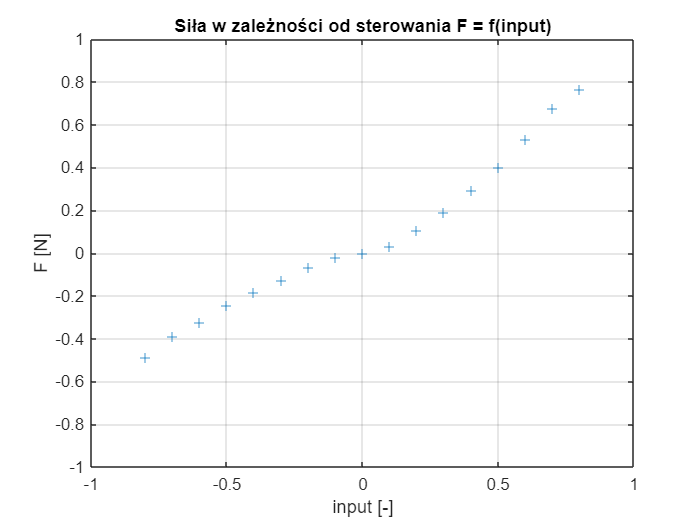

% Wykres siły ciągu w zależności od sterowania
figure
% Uwaga załadować współczynniki wielomianu z identyfikacja_silnika.mlx
plot(input, force, "+"); grid on;
title("Siła w zależności od sterowania F = f(input)");
xlabel("input [-]");
ylabel("F [N]");
xlim([-1 1]);
ylim([-1 1]);

% Wykres siły ciągu w zależności od obrotów 
figure
load("idenyfikacja_silnika_zmienne", "H_reversed")
rpm = polyval(H_reversed, input);
F = polyfit(rpm, force, 3)

F =     0.0000    0.0000    0.0000   -0.0025


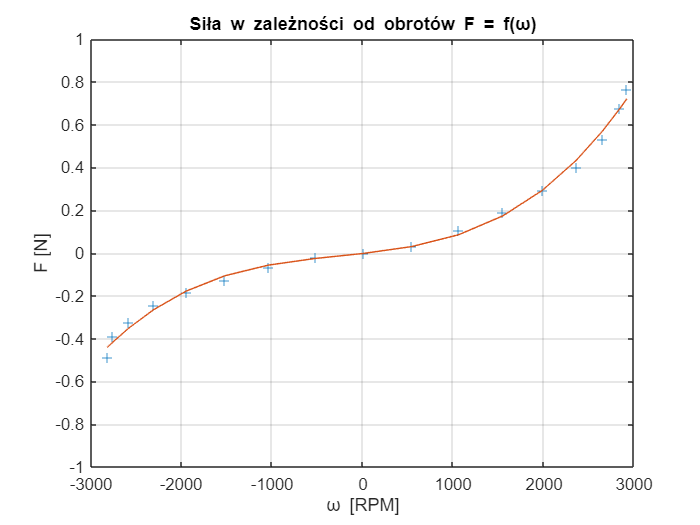

plot(rpm, force, "+"); grid on; hold on;
plot(rpm, polyval(F, rpm)); hold off;
title("Siła w zależności od obrotów F = f(\omega)");
xlabel("\omega [RPM]");
ylabel("F [N]");
xlim([-3000 3000]);
ylim([-1 1]);

% Zapis współczynników wielomianu
save("idenyfikacja_ciagu_zmienne.mat", "F")